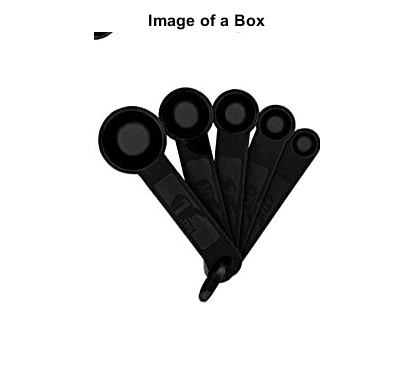

bI = imread('C:\Users\pooja\Desktop\blackspoon.jpg');
boxImage = rgb2gray(bI);
figure;
imshow(boxImage);
title('Image of a Box');

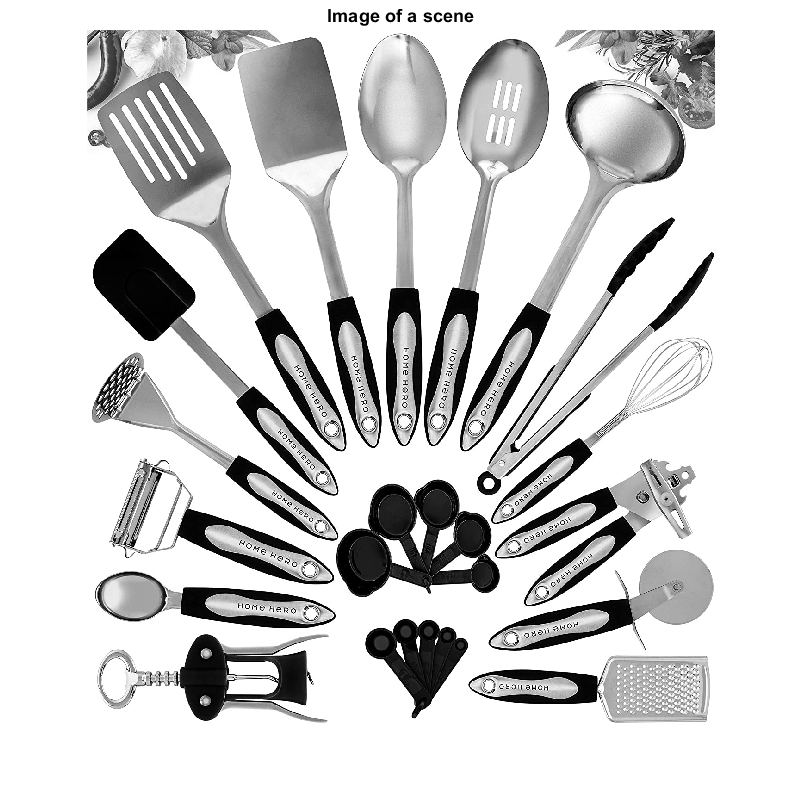

sI = imread('C:\Users\pooja\Desktop\spoonset.jpg');
sceneImage = rgb2gray(sI);
figure;
imshow(sceneImage);
title('Image of a scene');

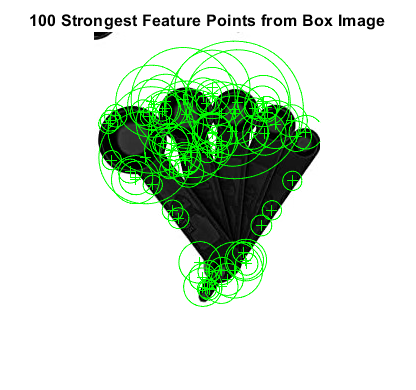

boxPoints = detectSURFFeatures(boxImage);

scenePoints = detectSURFFeatures(sceneImage);
figure;
imshow(boxImage);
title('100 Strongest Feature Points from Box Image');
hold on;
plot(selectStrongest(boxPoints, 100));

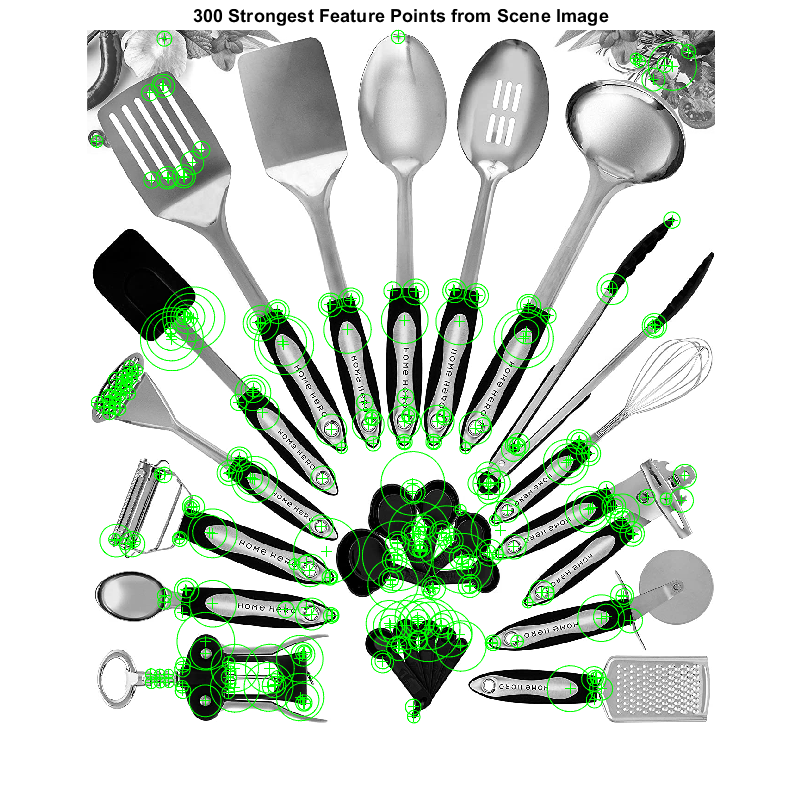

figure;
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

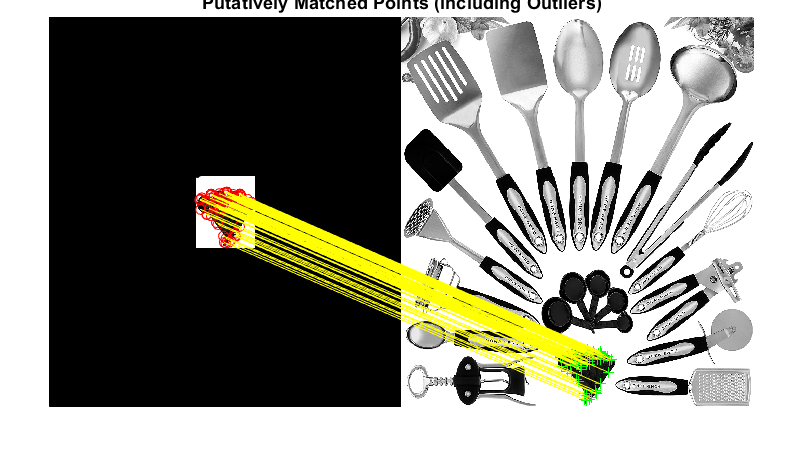

[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);
boxPairs = matchFeatures(boxFeatures, sceneFeatures);
matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

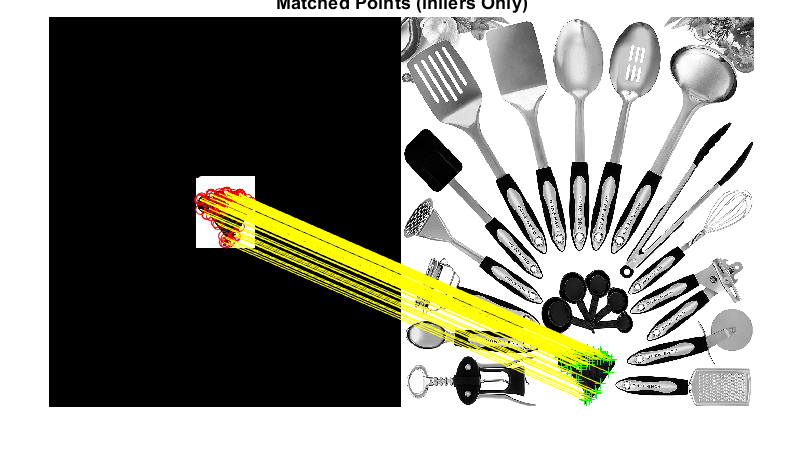

[tform, inlierIdx] = ...
    estimateGeometricTransform2D(matchedBoxPoints, matchedScenePoints, 'affine');
inlierBoxPoints   = matchedBoxPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);
figure;
showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

boxPolygon = [1, 1;...                           % top-left
        size(boxImage, 2), 1;...                 % top-right
        size(boxImage, 2), size(boxImage, 1);... % bottom-right
        1, size(boxImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon
newBoxPolygon = transformPointsForward(tform, boxPolygon)

newBoxPolygon = 5×2 single matrix
	1.0e+03 *

    0.5981    1.2189
    0.8230    1.2189
    0.8230    1.4950
    0.5981    1.4949
    0.5981    1.2189


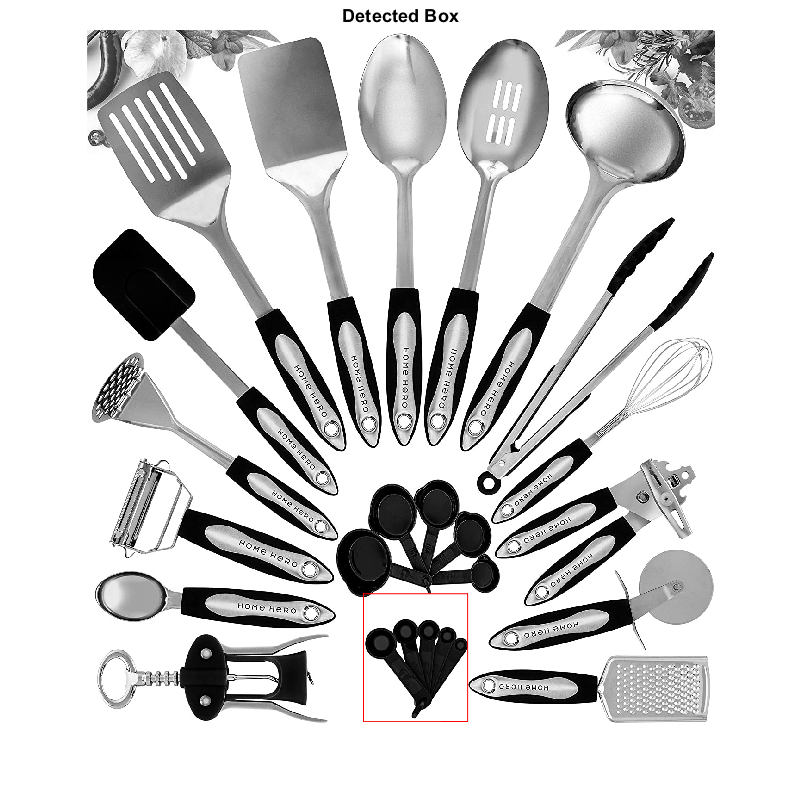

figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'r');
title('Detected Box');